# **EEG signal processing and Clasifier**

## **1.- Introduction: Motor imagery signals**

Motor imagery (MI) Brain computer interface employs the user's brain activity in the absence of any external stimuli. A standard concept in BCI is the translation of the user's intention via mental imagination of motor movement. The simple fact of intention helps in rehabilitation cases for patients with movement difficulties of mobility problems such as stroke patients. 

EEG signal do have a very low SNR. To improve the SNR the use of special filters and pre-processing signals may be a good stepping stone solution. An important part for BCI's is the characteristics extraction. Those characteristics are sent to a classifier to be able to tell which signal may be. On this script is meant to apply pre-processing and clasification of motor imagination EEG signals. 

The datasets are from 3 users who are doing 3 different actions. 

127: word

123: right hand movement

122: left hand movement

### 1.1.- Spectrum 

Function "calculo_espectro(input, fm)" calculates between 8-30Hz with a 2Hz resolution the spectrum from the input signal. As an example we could calculate the spectrum from a sinussoid signal with or without random noise. 

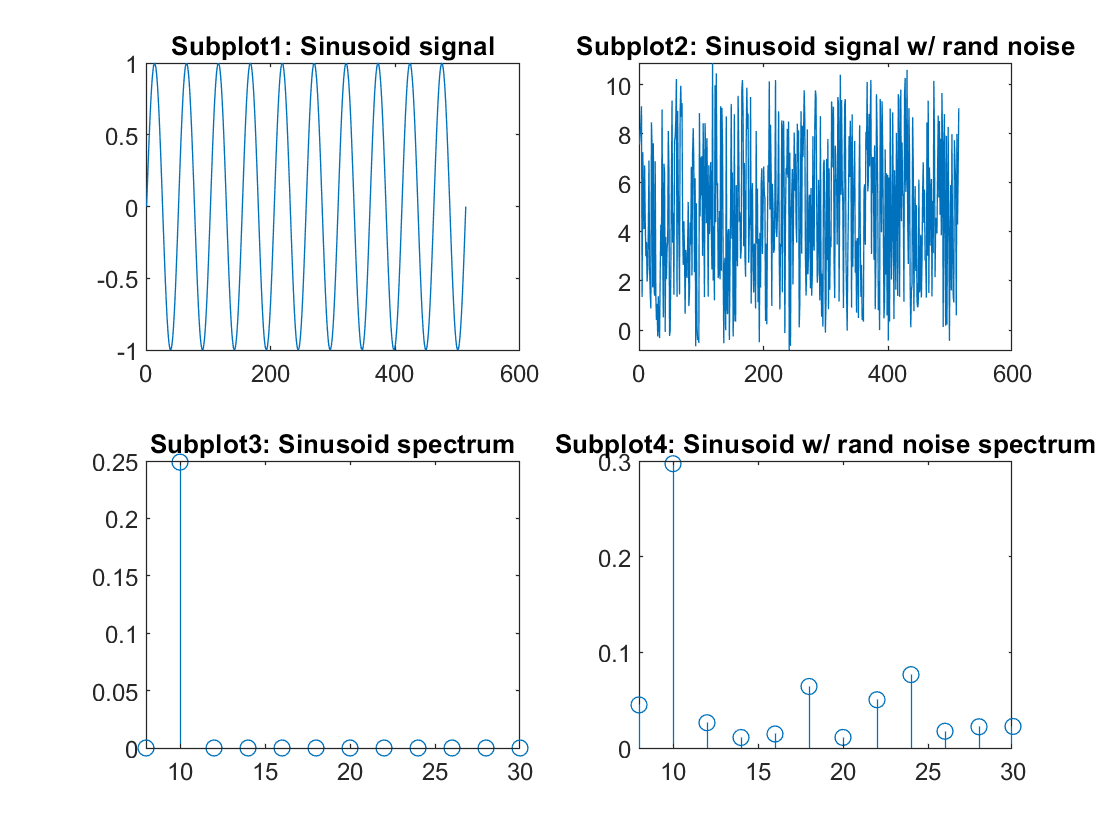

fm = 512;
t=0:1/fm:1;

freq= 10;
signal = 1*sin(2*pi*freq.*t);
signal_w = 1*sin(2*pi*freq.*t)+10*rand(1,length(t));


subplot(2,2,1)
plot(signal);
title("Subplot1: Sinusoid signal")
subplot(2,2,2)
plot(signal_w)
title("Subplot2: Sinusoid signal w/ rand noise")
subplot(2,2,3)
stem(8:2:30, calculo_espectro(signal, fm));
title("Subplot3: Sinusoid spectrum")
subplot(2,2,4)
stem(8:2:30, calculo_espectro(signal_w, fm));
title("Subplot4: Sinusoid w/ rand noise spectrum"); 

 The freq parameter can be modified as wanted.

## 2.- EEG Processing

The processing proces consists in the following steps.

1) Load user data

load('user#0091#20040101#01#reg001.mat'	);

2) Function output = processing (session